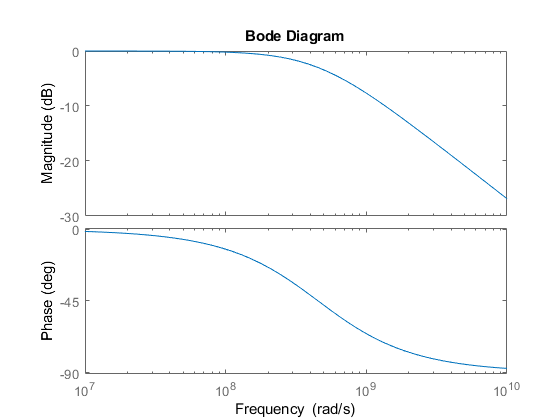

TimeCapacitance = capacitance / (65/142);
EngCapacitance = capacitance / (65/88);
Lpower = 0.84e-9 +  0.7e-9;
fosc = 1./(2.*pi.*sqrt(Lpower.*TimeCapacitance.*1e-12));
wosc = 2*pi.*fosc;
Rf = 2.2;
Cf = 1e-9;
numerator = 1;
denominator = [Rf*Cf,1];
filter = tf(numerator,denominator);
Gainperfreq = 1./sqrt(1+(wosc*Rf*Cf).^2);
bode(filter)

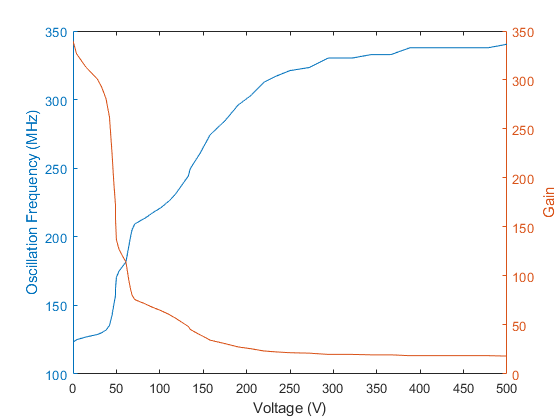

figure
yyaxis left
plot(voltage, fosc./1e6)
xlabel('Voltage (V)')
ylabel('Oscillation Frequency (MHz)')
yyaxis right
plot(voltage, Gainperfreq.*EngCapacitance)
ylabel('Gain')

%legend('Junction Temperature','Heatsink Temperature','Location', 'best');




